**Discretización de un sistema LTI de segundo orden de tiempo continuo**

Valores de los parámetros del sistema según la ecuación diferencial descrita en el documento de la tarea correspondiente

m=30;
b=20;
k=50;

Cálculo de los parámetros y de la función de transferencia en tiempo continuo

b1=b/m;
a1=b1;
b2=k/m;
a2=b2;
sys_s=tf([0 b1 b2],[1 a1 a2])

sys_s =
 
     0.6667 s + 1.667
  ----------------------
  s^2 + 0.6667 s + 1.667
 
Continuous-time transfer function.



Para discretizar el sistema se considerará el siguiente periodo de muestreo

Ts=0.1;

En este caso se utilizarán otras estrategias de discretización para sistemas de timepo continuo.

El primer método se conoce como "zoh", investigue en que consiste. Revise la ayuda de la función c2d(...) para que resuelva las posibles dudas

sysd=c2d(sys_s,Ts)

sysd =
 
   0.07245 z - 0.05635
  ----------------------
  z^2 - 1.919 z + 0.9355
 
Sample time: 0.1 seconds
Discrete-time transfer function.



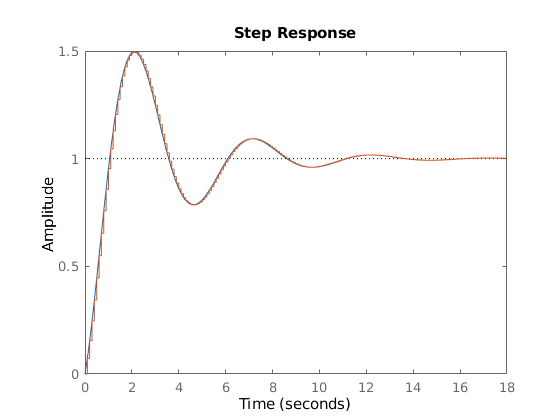

figure
hold on
step(sys_s)
step(sysd)
hold off

El siguiente método se conoce como invarianza impulsional, invetigue en que consiste

opt=c2dOptions('Method','impulse');
sysd=c2d(sys_s,Ts,opt)

sysd =
 
  0.06667 z^2 - 0.05005 z + 9.393e-20
  -----------------------------------
        z^2 - 1.919 z + 0.9355
 
Sample time: 0.1 seconds
Discrete-time transfer function.



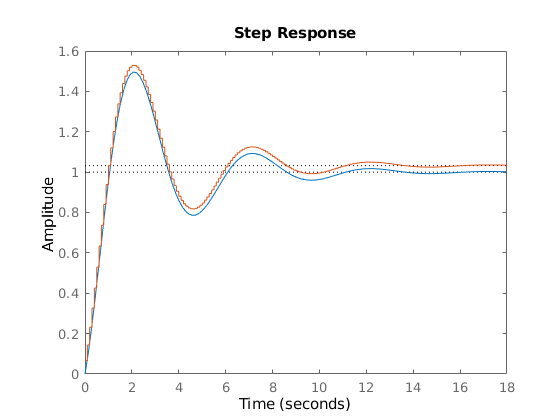

figure
hold on
step(sys_s)
step(sysd)
hold off

A continuación se probará el método de "Tustin", investigue en que consiste

opt=c2dOptions('Method','tustin');
sysd=c2d(sys_s,Ts,opt)

sysd =
 
  0.03614 z^2 + 0.008032 z - 0.02811
  ----------------------------------
        z^2 - 1.92 z + 0.9357
 
Sample time: 0.1 seconds
Discrete-time transfer function.



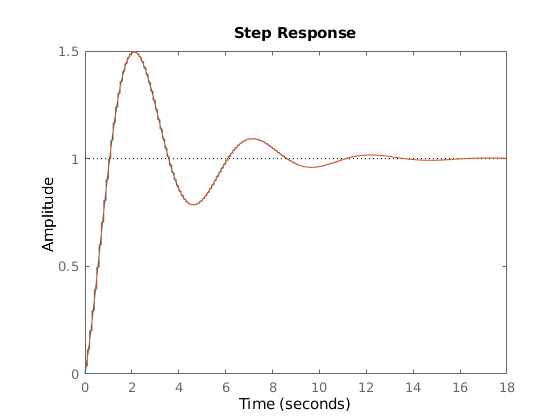

figure
hold on
step(sys_s)
step(sysd)
hold off

Realice variaciones en el periodo de muestreo y observe las diferencias que presenta cada método. Observe que las funciones de transferencia de tiempo discreto no son iguales ¿Por qué se dará esto?. Revise que otras opciones se pueden aplicar a cada uno de los métodos presentados y que otros métodos están disponibles para ser usados.